# フィルタリングと平滑化

%関数の読み込み
addpath('functions')
rng(1000)
clear global;
%時系列数
N = 100;
%パラメータ設定
phi1 = 0.97; % AR in state of wind speed
gam = 3; % constants in wind speed
mu_g = 0.0; % location in wind direction for transition
mu_f = 0.0; % location in wind direction for marginal
rho_f =0.1; % consentration in wind direction for marginal
V = 20;
mu_rho = 0.5;
sig_rho=1;
par1 = [phi1 gam mu_g mu_f rho_f V mu_rho sig_rho];

%塩浜先生がお作りしたものを使用しています
sample = csvread("sample.csv",1,1);
%観測変数の取り出し(観測変数としては使わないものもある)
theta = sample(:,1);
v =sample(:,2);
rho =sample(:,3);
alpha =sample(:,4);

y = theta;
v = v;
r = rho;
alp = alpha;

%リサンプリングされた箇所の確認　ここは計算の関係でCPUでやってます
[pfOut1, pfOut2, wt, pfOut1_mean, pfOut2_mean, rho1] = particlefilter_reallycorrect2(par1, y, v, r, alp, 500);

it = 4

it = 10

it = 14

it = 17

it = 20

it = 25

it = 33

it = 41

it = 49

it = 53

it = 59

it = 65

it = 70

it = 72

it = 76

it = 88

it = 97

%平滑化はGPUなので一瞬で終ります
[smwt] = particlesmoother2(phi1, sig_rho, mu_rho, pfOut1, rho1, wt);

### alpha

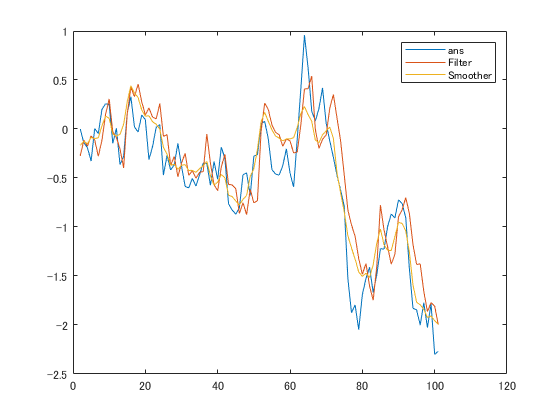

sm_mean = diag(smwt(2:(N+1),:) * gpuArray(pfOut1(2:(N+1),:)'));
plot(2:(N+1),alp)
hold on
plot(2:(N+1),pfOut1_mean(2:(N+1)))
hold on
plot(2:(N+1),sm_mean)
legend('ans','Filter','Smoother')
hold off

### y

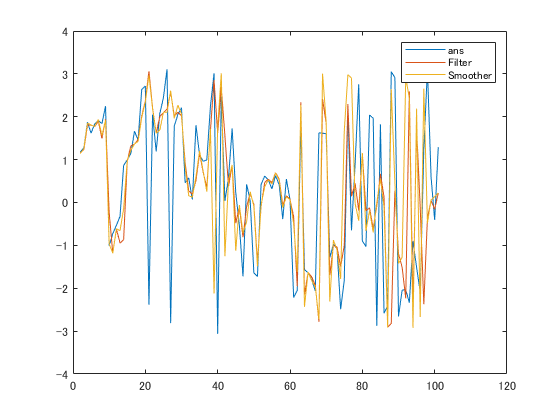

sin_mean =  diag(sin(pfOut2(2:(N+1),:)) * wt(2:N+1,:)');
cos_mean =  diag(cos(pfOut2(2:(N+1),:)) * wt(2:N+1,:)');
y_filter = arrayfun(@(x,y) circular_mean(x,  y), sin_mean,cos_mean);
sin_mean =  diag(sin(pfOut2(2:(N+1),:)) * gather(smwt(2:N+1,:)'));
cos_mean =  diag(cos(pfOut2(2:(N+1),:)) * gather(smwt(2:N+1,:)'));
y_smoother = arrayfun(@(x,y) circular_mean(x,  y), sin_mean,cos_mean);
plot(2:(N+1),y)
hold on
plot(2:(N+1),y_filter)
hold on
plot(2:(N+1),y_smoother)
legend('ans','Filter','Smoother')
hold off

### rho

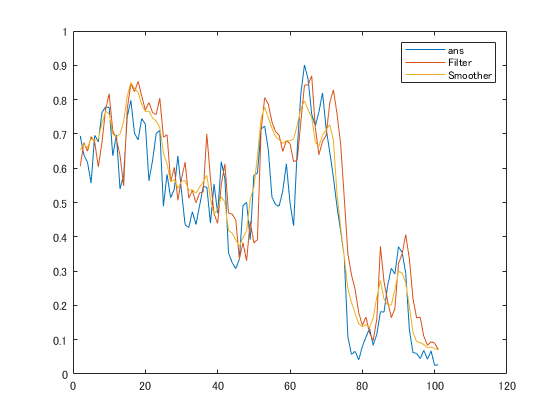

plot(2:(N+1),rho)
hold on
plot(2:(N+1),(0.95*tanh(par1(8) .* pfOut1_mean(2:N+1)+par1(7)) + 1)/2)
hold on
plot(2:(N+1),(0.95*tanh(par1(8).* sm_mean+par1(7)) + 1)/2)
legend('ans','Filter','Smoother')
hold off

### v

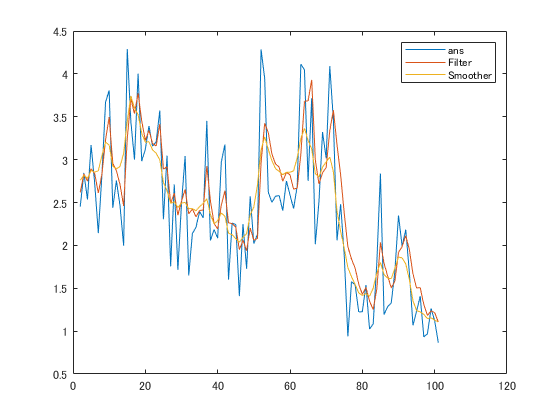

plot(2:(N+1),v)
hold on
plot(2:(N+1),par1(2)*exp(pfOut1_mean(2:N+1)/2))
hold on
plot(2:(N+1),par1(2)*exp(sm_mean/2))
legend('ans','Filter','Smoother')
hold off